'local' プロファイルを使用して並列プール (parpool) を起動中...
並列プールに接続済み (ワーカー数: 8)。


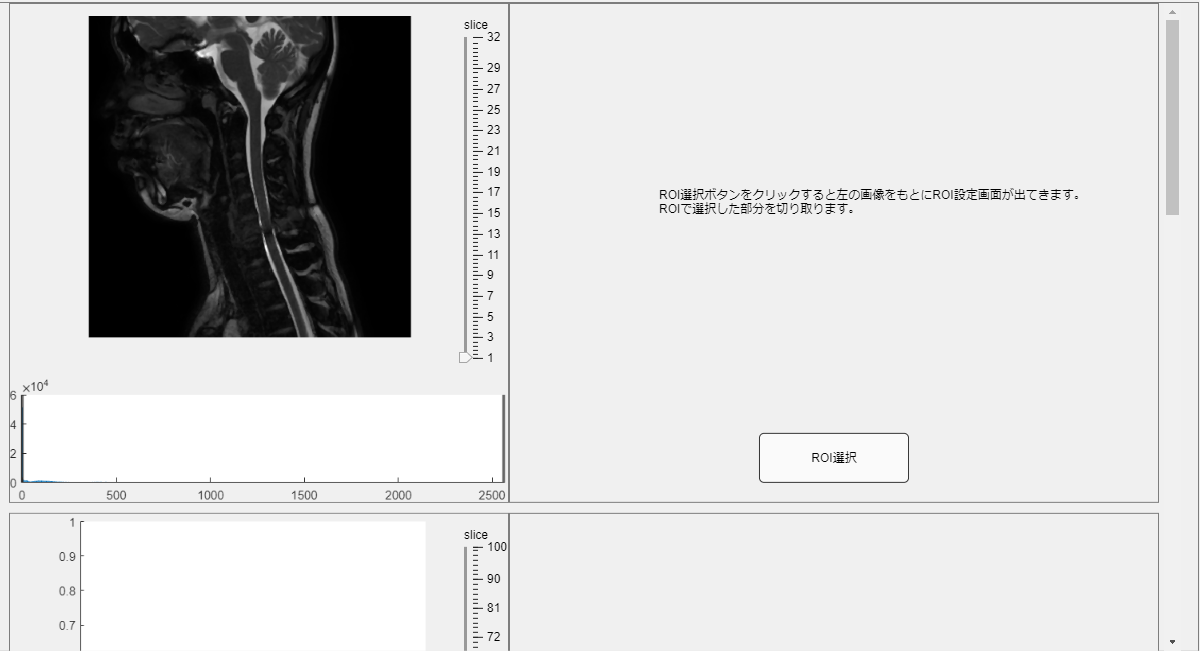

clc
dcmHandler = scripts.dicomHandler.DICOMHandler();
dcmHandler.readDICOMDIR();
[dcmInfo, dcmImg] = dcmHandler.getPreview();
dcmImgs = dcmHandler.readAllImage();



%getCurrentMousePosition
%Axes上にマウスポインタがフロートした時にイベント発火
%マウスポインタポジション-> rawData配列の位置指定 -> 表示
%表示listenerイベントlisten
%これで真の信号値表示はOK
% scripts.imtool3D.imtool3D_nawaMod("I", dcmImgs)
%ヒストグラム上のX軸信号地はhistX取得でOK




%↑ができたら次は階調処理の高速化
%アルゴリズムとしてはhistXのCategoryにのみ階調処理をおこなう
%階調処理前：階調処理後　の関連構造を保ちつつ、
%rawDataに対して階調処理前に当てはまるものを階調処理後に変える
%logical配列応用するとできるかも？

%↑ができたら次はウィンドウ調整のMinMaxValidation